## Wing Design

clear
% Set default figure size (in inches)
% set(groot, 'defaultFigureUnits', 'inches');
% set(groot, 'defaultFigurePosition', [1, 1, 6, 4]); % Width = 6 inches, Height = 4 inches
% 
% % Set default font settings for all text in plots
% set(groot, 'defaultAxesFontName', 'Times New Roman');
% set(groot, 'defaultAxesFontSize', 12); % Font size for axis labels and ticks
% set(groot, 'defaultTextFontSize', 12); % Font size for text in the plot
% set(groot, 'defaultAxesTitleFontSizeMultiplier', 1.2); % Slightly larger title
% set(groot, 'defaultLegendFontSize', 11); % Font size for legend text
% 
% % Set default line and marker settings
% set(groot, 'defaultLineLineWidth', 1.5); % Default line width
% set(groot, 'defaultLineMarkerSize', 8); % Default marker size
% 
% % Set default box and grid
% set(groot, 'defaultAxesBox', 'on'); % Enable box around plots by default
% set(groot, 'defaultAxesGridLineStyle', '-'); % Solid grid lines
% set(groot, 'defaultAxesXGrid', 'on'); % Enable grid for X axis
% set(groot, 'defaultAxesYGrid', 'on'); % Enable grid for Y axis

global airfoil cruise1 cruise2 C_cruise Wto Swet_SrefWing Swet_SrefBody l_d W_Sdes bdes nult bodyDiameter Srefdes Damping tolerance bodyLength W_ZF_Nowing Wpayload
Wpayload = 8.7176e3*9.81;
bodyDiameter = 6.38;
Damping = 0.03;
tolerance = 1e-4;
cruise1 = AirCondition();
cruise1.M = 0.83;
cruise1.h = convlength(28000, 'ft','m');

cruise2 = AirCondition();
cruise2.V = convvel(400, 'kts', 'm/s');
cruise2.h = convlength(18000, 'ft','m');
cruise2 = cruise2.calcM();

C_cruise = 0.5 ./ 3600;
Wto0 = 4.2188*1e5*9.81;
Swet_SrefWing = 2.2;
bodyLength = 80;
Swet_SrefBody = pi*bodyDiameter*bodyLength*1.1./Srefdes;
l_d = bodyLength/bodyDiameter;

Srefdes = 548.7;
W_Sdes = Wto0/Srefdes;
Wto = Wto0;
nult = 3.75;

## 1.Design CL

CLdesC1 = 0.4623;
CLdesC2 = 0.3008;

## 2.Airfoil Selection

1.Choose a t/c ratio optimum for the cruise speed

2.Choose a CLopt (at L/D max or called drag-bucket) close to design CL

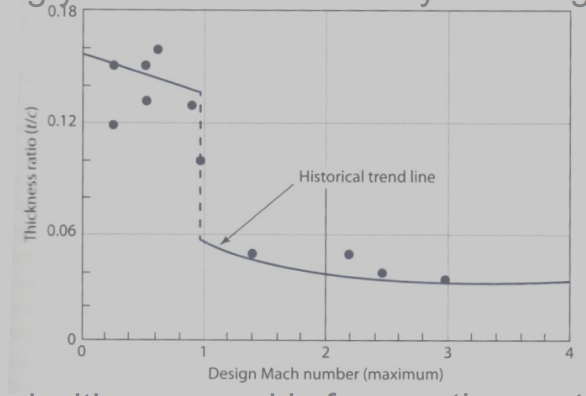

kA = 0.95;
Lambdades = 20 * pi / 180;
MDD = 0.85;

% Define paths
polarPath = '../Airfoils/Airfoil H polar data'; % Directory for polar data
XYPath = '../Airfoils/Airfoil H XY data';      % Directory for XY data

% Read polar data files, excluding unwanted entries
polarFiles = dir(polarPath);
polarNames = {polarFiles(~[polarFiles.isdir]).name};
polarNames = polarNames(~contains(polarNames, '.DS_Store')); % Remove unwanted files

% Read XY data files, excluding unwanted entries
XYFiles = dir(XYPath);
XYNames = {XYFiles(~[XYFiles.isdir]).name};
XYNames = XYNames(~contains(XYNames, '.DS_Store')); % Remove unwanted files

% Check if the number of polar and XY files match
if length(polarNames) ~= length(XYNames)
    error('Mismatch between the number of polar and XY files. Please ensure they align.');
end

% Initialize results
FF = zeros(1, length(polarNames));
stallAngle = zeros(1, length(polarNames));
CLmax = zeros(1, length(polarNames));
L_Ddes = zeros(1, length(polarNames));
t_c = zeros(1, length(polarNames));

% Main loop to process airfoil data
figure(4);
clf;
for i = 1:length(polarNames)
    thisairfoil = Airfoil();
    
    % Extract polar and shape file names
    polarName = polarNames{i};
    shapeName = XYNames{i};
    
    % Read airfoil data
    thisairfoil = thisairfoil.readPolar(string(fullfile(polarPath, polarName)));
    thisairfoil = thisairfoil.readShape(string(fullfile(XYPath, shapeName)));
    thisairfoil = thisairfoil.interpShape(9);
    
    % Compute aerodynamic properties
    FF(i) = (1 + 0.6 .* thisairfoil.t_c ./ thisairfoil.x_cm + 100 .* thisairfoil.t_c .^ 4) .* ...
            (1.34 .* MDD .^ 0.18 .* (cos(Lambdades)) .^ 0.28);
    stallAngle(i) = thisairfoil.alphaSPos;
    CLmax(i) = max(thisairfoil.Cl);
    L_Ddes(i) = thisairfoil.L_DatCL(CLdesC1);
    t_c(i) = thisairfoil.t_c;
end


% Compute airfoil index
airfoilIdx = CLmax .* L_Ddes;

% Extract shortened polar names for table
polarNames_new = cellfun(@(x) extractBetween(x, 4, 14), polarNames, 'UniformOutput', false);

% Create a table of results
airfoilData = table(string(polarNames_new)', FF', t_c', stallAngle' .* 180 / pi, CLmax', L_Ddes', airfoilIdx', ...
    'VariableNames', {'Name', 'Skin Friction Form Factor', 't/c', 'stallAngle', 'Clmax', 'L/D design', 'CLmax x L/D design'});

% Display table
disp(airfoilData);

        Name         Skin Friction Form Factor       t/c        stallAngle    Clmax     L/D design    CLmax x L/D design
    _____________    _________________________    __________    __________    ______    __________    __________________

    "n0009sm-il-"             1.2795              0.00079713      12.75       1.2089      57.655              69.7      
    "n0012-il-10"             1.6162                  0.1213       15.5       1.3892       62.73            87.145      
    "n63010a-il-"             1.5167                 0.10041      10.25       1.0001      54.605             54.61      
    "n63012a-il-"             1.5773                 0.12052      13.25       1.1738      59.247            69.544      
    "n63015a-il-"             1.684


% Apply the rounding function to each numeric column
% airfoilData.("Skin Friction Form Factor") = roundToSF(airfoilData.("Skin Friction Form Factor"));
% airfoilData.("t/c") = roundToSF(airfoilData.("t/c"));
% airfoilData.stallAngle = roundToSF(airfoilData.stallAngle);
% airfoilData.Clmax = roundToSF(airfoilData.Clmax);
% airfoilData.("L/D design") = roundToSF(airfoilData.("L/D design"));
% airfoilData.("CLmax x L/D design") = roundToSF(airfoilData.("CLmax x L/D design"));





figure(7);
clf;

% Loop through each airfoil file
for i = 1:length(polarNames)
    thisairfoil = Airfoil();
    
    % Extract polar and shape file names
    polarName = polarNames{i};
    shapeName = XYNames{i};
    
    % Read airfoil data
    thisairfoil = thisairfoil.readPolar(string(fullfile(polarPath, polarName)));
    thisairfoil = thisairfoil.readShape(string(fullfile(XYPath, shapeName)));
    thisairfoil = thisairfoil.interpShape(12);
    
    % Generate a random RGB color
    randomColor = rand(1, 3);
    
    % Plot Cm vs alpha
    plot(thisairfoil.alpha .* 180 / pi, thisairfoil.Cm, 'LineWidth', 2, 'Color', randomColor);
    hold on;
end

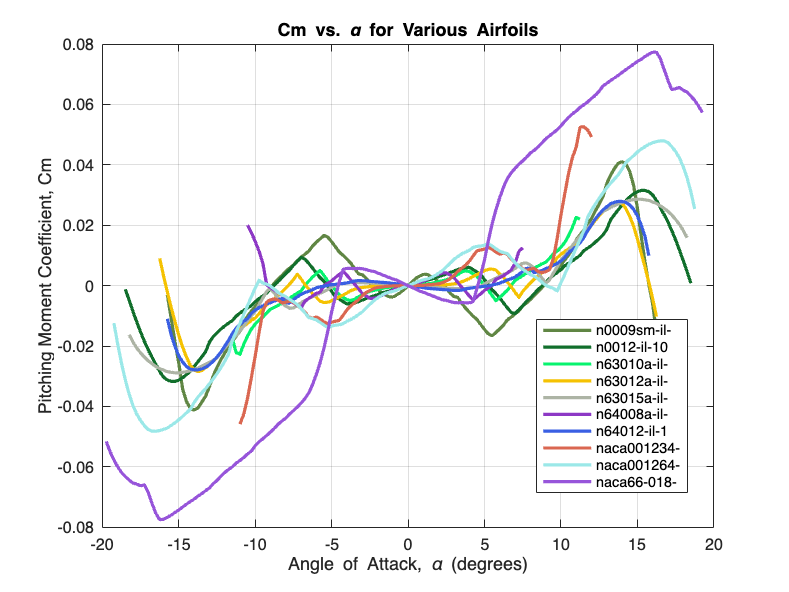


% Convert polarNames_new to string array for the legend
legend(string(polarNames_new), 'Interpreter', 'none', 'Location', 'best');
xlabel("Angle of Attack, \alpha (degrees)");
ylabel("Pitching Moment Coefficient, Cm");
grid on;
title("Cm vs. \alpha for Various Airfoils");


% Save the figure as a high-resolution PNG image
%saveas(gcf, 'Cm_vs_alpha.png');  % Default resolution
% Alternatively, use print with a higher DPI:
%print(gcf, 'Cm_vs_alpha_hd.png', '-dpng', '-r300');  % Save as PNG with 300 DPI for high resolution

figure(8);
clf;

% Loop through each airfoil file
for i = 1:length(polarNames)
    thisairfoil = Airfoil();
    
    % Extract polar and shape file names
    polarName = polarNames{i};
    shapeName = XYNames{i};
    
    % Read airfoil data
    thisairfoil = thisairfoil.readPolar(string(fullfile(polarPath, polarName)));
    thisairfoil = thisairfoil.readShape(string(fullfile(XYPath, shapeName)));
    thisairfoil = thisairfoil.interpShape(9);
    
    % Generate a random RGB color
    randomColor = rand(1, 3);
    
    % Plot Cm vs alpha
    plot(thisairfoil.alpha .* 180 / pi, thisairfoil.Cl, 'LineWidth', 2, 'Color', randomColor);
    hold on;
end

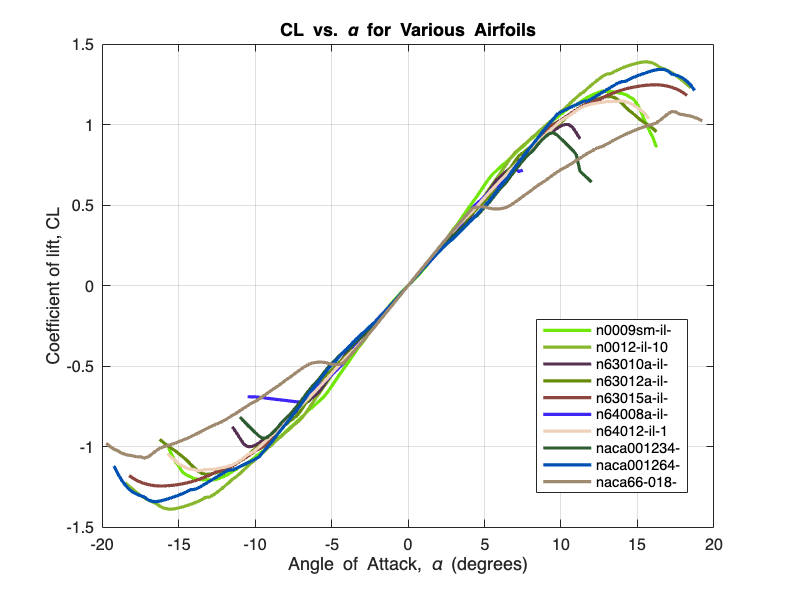


% Convert polarNames_new to string array for the legend
legend(string(polarNames_new), 'Interpreter', 'none', 'Location', 'best');
xlabel("Angle of Attack, \alpha (degrees)");
ylabel("Coefficient of lift, CL");
grid on;
title("CL vs. \alpha for Various Airfoils");

% Save the figure as a high-resolution PNG image
%saveas(gcf, 'CL_vs_alpha.png');  % Default resolution
% Alternatively, use print with a higher DPI:
print(gcf, 'CL_vs_alpha_hd.png', '-dpng', '-r300');  % Save as PNG with 300 DPI for high resolution

### Conclusion:

% polarName = "xf-sc20714-il-1000000.csv";
% shapeName = "sc20714.dat.txt";
% airfoil = Airfoil();
% airfoil = airfoil.readPolar(string(fullfile(polarPath, polarName)));
% airfoil = airfoil.readShape(string(fullfile(XYPath, shapeName)));
% airfoil = airfoil.interpShape(9);

## 3.Shape

1.Use MDO to get best geometry

    -Make sure it is applicable to double-tapered, swept wing

    -At each iteration inside MDO, calculate the optimum twist to give elliptical lift distribution

    -Use a validated wing weight estimation model

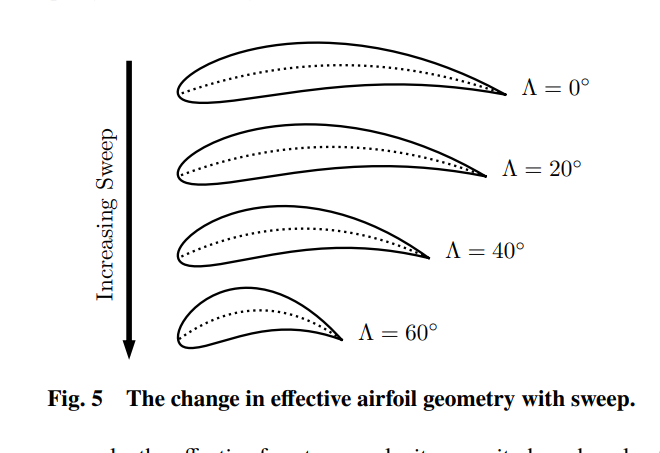


% % Initial guess
% % wing span fixed to 65
% bdes = 65;
% x0 = [13, 10, 3.5, 30*pi/180, 30*pi/180, 12, deg2rad(1.3)];
% wing0 = x2wing(x0);
% %x0 = [cr, ck, ct, Lambdain50, Lambdaout50, yk, maxtwist in radians]
% % Design variables 
% lb = [13, 10, 3.5, 25*pi/180, 25*pi/180, 12, deg2rad(0)];
% %lb(7) = deg2rad(3);
% ub = [17, 15, 5, 35*pi/180, 35*pi/180, 14, deg2rad(5)];
% %ub(7) = deg2rad(3);
% 
% cruise1 = cruise1.init(wing0.cbar);
% [CL, CD, CLy, CDprofile0] = LLESwept(wing0, airfoil, cruise1)
% W_ZF_Nowing = Wto0 - Wto0 * 0.5 - Wpayload - wingWeightRaymer(wing0,airfoil,Wto,nult,wing0.SREF*0.0612);

% %wingMDO(x0)
% Optimization options
% options = optimoptions('fmincon', 'Display', 'iter', 'Algorithm', 'sqp');
% % Run the optimization
% [x_opt, fval] = fmincon(@wingMDO, x0, [], [], [], [], lb, ub, @constraintFunction, options);
% wing_opt =  x2wing(x_opt);
% wing_opt = wing_opt.calcSref();
% figure(1)
% clf;
% subplot(2,1,1)
% wing0.plotWing()
% title("Initial")
% axis equal
% subplot(2,1,2)
% wing_opt.plotWing()
% title("Optimzed")
% yline(bodyDiameter/2)
% hold on
% yline(-bodyDiameter/2)
% axis equal
% 
% save("wing_opt.mat","wing_opt")

Analyse the aero characteristic of opt wing:

During cruise1:

%load("wing_opt.mat")
% cruise1 = cruise1.init(wing_opt.cbar)
% [CL1, CDi1, Cly1, CDprofile1] = LLESwept(wing_opt, airfoil, cruise1)
% CDF1 = CDFfun(cruise1.M, cruise1.Re, wing_opt, airfoil.x_cm, airfoil.t_c, l_d, Swet_SrefWing, Swet_SrefBody);
% CDW1 = CDWfun(wing_opt,Cly1,cruise1.M,airfoil.t_c);
% CDtotal1 = CDF1 + CDW1 + CDi1 + CDprofile1;
% 
% disp(["L/D: ", CL1/ CDtotal1])
% disp(["CLclean: ", CL1])
% disp(["Sref: ", wing_opt.SREF])
% disp(["Maximum twist(degrees)", wing_opt.twist_max * 180/pi])
% disp(["Inner sweep angle(degrees)", wing_opt.Lambdain50 * 180/pi])
% disp(["Outer sweep angle(degrees)", wing_opt.Lambdaout50 * 180/pi])
% disp(wing_opt)

## 4.Dihedral

-G17 presents a quantitative estimate

## 5.HLD

1.Calculate CLmax requirement at landing and takeoff

2.Select

## 6.Control Surfaces

## 7.Tailplane design

## 8.Nose shape optimization